# Figure 7 -   Figure supplement 1

## initialize environment

defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Supp Figure 7p1 - In vivo bilateral ablations');

%colors
lt_org = [255, 166 , 38]/255;
dk_org = [255, 120, 0]/255;
lt_blue = [50, 175, 242]/255;
dk_blue = [0, 13, 242]/255;

## Examples

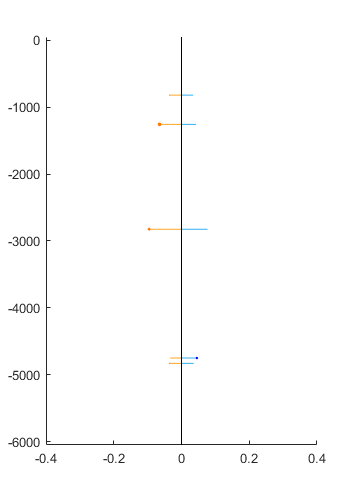

h1 =   Figure (339) with properties:

      Number: 339
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1.8000 1.2000]
       Units: 'inches'

  Show all properties


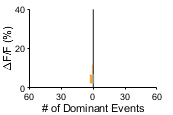

Rdom = 1

tempPkData = 	1.0e+03 *

    0.8190    0.0000    0.8190    0.0000    0.0000    0.0030    0.0010
    1.2560    0.0001    1.2560    0.0000    0.0000    0.0020    0.0010
    2.8240    0.0001    2.8240    0.0001    0.0000    0.0010    0.0010
    4.8300    0.0000    4.8300    0.0000    0.0000    0.0010    0.0010


LIC: 3 peaks total, 2 corresponding RIC peaks.
RIC: 4 peaks total, 2 corresponding LIC peaks.
Mean RIC amplitude: 0.047022
Mean LIC amplitude: 0.052986
.\Data\Experiment-783\ICinfo16_dFoF


%bilateral ablation
    bilablfile = '.\Data\Experiment-783\ICinfo16_dFoF.mat';
    load(bilablfile);
    [filePath name ext] = fileparts(bilablfile);
    [stats,pkData] = P2ry1_findICpeaksdFoF(ICsignal,filePath,'dFoF',1);

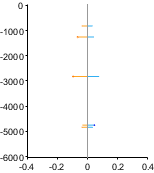

    [figh1, figh2] = lollipopPlot(pkData);
    set(0,'CurrentFigure', figh1);
    figQuality(figh1,gca,[1.6 1.8]);
    export_fig(['.\EPS Panels\KObilabllolli.eps'], '-eps', '-nocrop')
    
    set(0,'CurrentFigure', figh2)
    figQuality(figh2,gca,[1.4 .95]);
    export_fig(['.\EPS Panels\KObilablexHisto.eps'], '-eps', '-nocrop')


%bilateral ablation
    KOfile = '..\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-591\ICinfo16_dFoF.mat';
    load(KOfile);
    [filePath name ext] = fileparts(KOfile);
    [stats,pkData] = P2ry1_findICpeaksdFoF(ICsignal,filePath,'dFoF',0);

Rdom = 63

tempPkData = 	1.0e+03 *

    0.0460    0.0002    0.0540    0.0001    0.0001    0.0010    0.0010
    0.0900    0.0001    0.0930    0.0001    0.0000    0.0010    0.0010
    0.3340    0.0001    0.3320    0.0000    0.0001    0.0010    0.0010
    0.3900    0.0002    0.3900    0.0002    0.0000    0.0020    0.0010
    0.4030    0.0003    0.4030    0.0001    0.0002    0.0020    0.0010
    0.5160    0.0001    0.5160    0.0000    0.0000    0.0020    0.0010
    0.6130    0.0001    0.6130    0.0000    0.0000    0.0020    0.0010
    0.6540    0.0000    0.6540    0.0000    0.0000    0.0020    0.0010
    0.7120    0.0002    0.7120    0.0000    0.0001    0.0010    0.0010
    0.9690    0.0001    0.9690    0.0001    0.0001    0.0020    0.0010


LIC: 87 peaks total, 50 corresponding RIC peaks.
RIC: 82 peaks total, 50 corresponding LIC peaks.
Mean RIC amplitude: 0.10391
Mean LIC amplitude: 0.10012
..\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-591\ICinfo16_dFoF


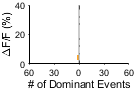

    [figh1, figh2] = lollipopPlot(pkData);
    set(0,'CurrentFigure', figh1);
    figQuality(figh1,gca,[1.6 1.8]);
    export_fig(['.\EPS Panels\bilateralabl_lolli.eps'], '-eps', '-nocrop')

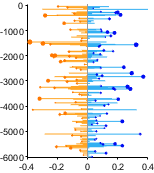

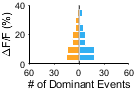

    
    set(0,'CurrentFigure', figh2)
    figQuality(figh2,gca,[1.4 .95]);
    export_fig(['.\EPS Panels\bilateralabl_exHisto.eps'], '-eps', '-nocrop')

## Group data

%ko
    wtFiles = loadFileList('..\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\*\*ICinfo16_dFoF.mat');
    [WT_stats, figh, counts] = groupData_histograms(wtFiles);

M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-338\ICinfo16_dFoF.mat


Rdom = 55

tempPkData = 	1.0e+03 *

    0.4210    0.0001    0.4210    0.0000    0.0000    0.0020    0.0010
    0.4700    0.0001    0.4690    0.0001    0.0000    0.0010    0.0010
    0.6130    0.0001    0.6130    0.0001    0.0001    0.0020    0.0010
    0.7120    0.0001    0.7120    0.0000    0.0001    0.0020    0.0010
    0.7350    0.0001    0.7350    0.0000    0.0001    0.0020    0.0010
    0.7780    0.0000    0.7780    0.0000    0.0000    0.0020    0.0010
    0.8180    0.0001    0.8130    0.0000    0.0000    0.0010    0.0010
    0.8540    0.0001    0.8570    0.0001    0.0000    0.0010    0.0010
    0.9840    0.0002    0.9830    0.0002    0.0000    0.0010    0.0010
    1.1080    0.0002    1.1080    0.0001    0.0001    0.0020    0.0010


LIC: 81 peaks total, 43 corresponding RIC peaks.
RIC: 80 peaks total, 43 corresponding LIC peaks.
Mean RIC amplitude: 0.070487
Mean LIC amplitude: 0.083963
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-338\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-344\ICinfo16_dFoF.mat


Rdom = 36

tempPkData = 	1.0e+03 *

    0.0670    0.0000    0.0670    0.0000    0.0000    0.0020    0.0010
    0.1850    0.0001    0.1850    0.0001    0.0001    0.0020    0.0010
    0.2670    0.0002    0.2700    0.0001    0.0001    0.0010    0.0010
    0.2980    0.0001    0.2980    0.0001    0.0000    0.0030    0.0010
    0.3110    0.0001    0.3110    0.0000    0.0001    0.0020    0.0010
    0.3460    0.0002    0.3460    0.0001    0.0002    0.0020    0.0010
    0.3560    0.0002    0.3560    0.0001    0.0001    0.0020    0.0010
    0.5660    0.0001    0.5660    0.0000    0.0000    0.0020    0.0010
    0.6590    0.0000    0.6590    0.0000    0.0000    0.0020    0.0010
    0.8260    0.0001    0.8260    0.0000    0.0001    0.0020    0.0010


LIC: 51 peaks total, 17 corresponding RIC peaks.
RIC: 45 peaks total, 17 corresponding LIC peaks.
Mean RIC amplitude: 0.049704
Mean LIC amplitude: 0.057825
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-344\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-354\ICinfo16_dFoF.mat


Rdom = 57

tempPkData = 	1.0e+03 *

    0.0900    0.0002    0.0900    0.0001    0.0001    0.0020    0.0010
    0.1160    0.0002    0.1160    0.0000    0.0002    0.0020    0.0010
    0.2150    0.0004    0.2180    0.0002    0.0002    0.0010    0.0010
    0.2390    0.0006    0.2450    0.0005    0.0001    0.0010    0.0010
    0.5850    0.0003    0.5840    0.0002    0.0001    0.0010    0.0010
    0.6310    0.0006    0.6290    0.0002    0.0004    0.0010    0.0010
    0.8100    0.0001    0.8100    0.0000    0.0001    0.0020    0.0010
    0.9540    0.0004    0.9540    0.0003    0.0000    0.0030    0.0010
    0.9690    0.0006    0.9690    0.0002    0.0003    0.0020    0.0010
    0.9920    0.0003    0.9920    0.0001    0.0002    0.0030    0.0010


LIC: 73 peaks total, 46 corresponding RIC peaks.
RIC: 81 peaks total, 46 corresponding LIC peaks.
Mean RIC amplitude: 0.12608
Mean LIC amplitude: 0.13065
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-354\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-360\ICinfo16_dFoF.mat


Rdom = 49

tempPkData = 	1.0e+03 *

    0.0850    0.0001    0.0790    0.0000    0.0001    0.0010    0.0010
    0.2440    0.0001    0.2440    0.0000    0.0000    0.0020    0.0010
    0.3650    0.0000    0.3650    0.0000    0.0000    0.0020    0.0010
    0.4370    0.0004    0.4370    0.0002    0.0001    0.0010    0.0010
    0.5700    0.0000    0.5700    0.0000    0.0000    0.0020    0.0010
    0.6450    0.0001    0.6450    0.0000    0.0001    0.0020    0.0010
    0.7130    0.0001    0.7140    0.0000    0.0001    0.0010    0.0010
    0.8420    0.0000    0.8420    0.0000    0.0000    0.0020    0.0010
    1.0080    0.0002    1.0080    0.0001    0.0000    0.0020    0.0010
    1.1750    0.0000    1.1750    0.0000    0.0000    0.0020    0.0010


LIC: 57 peaks total, 28 corresponding RIC peaks.
RIC: 65 peaks total, 28 corresponding LIC peaks.
Mean RIC amplitude: 0.070177
Mean LIC amplitude: 0.062635
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-360\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-361\ICinfo16_dFoF.mat


Rdom = 52

tempPkData = 	1.0e+03 *

    0.1290    0.0006    0.1390    0.0005    0.0001    0.0010    0.0010
    0.2090    0.0001    0.2090   -0.0000    0.0001    0.0020    0.0010
    0.2350    0.0000    0.2350    0.0000    0.0000    0.0030    0.0010
    0.2560    0.0001    0.2560    0.0000    0.0000    0.0020    0.0010
    0.2900    0.0001    0.2900    0.0000    0.0001    0.0020    0.0010
    0.4400    0.0001    0.4400    0.0000    0.0000    0.0020    0.0010
    0.4680    0.0001    0.4680    0.0000    0.0000    0.0020    0.0010
    0.5120    0.0004    0.5110    0.0002    0.0002    0.0010    0.0010
    0.5320    0.0004    0.5340    0.0002    0.0002    0.0010    0.0010
    0.7460    0.0004    0.7440    0.0002    0.0002    0.0010    0.0010


LIC: 52 peaks total, 26 corresponding RIC peaks.
RIC: 66 peaks total, 26 corresponding LIC peaks.
Mean RIC amplitude: 0.082704
Mean LIC amplitude: 0.074333
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-361\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-591\ICinfo16_dFoF.mat


Rdom = 63

tempPkData = 	1.0e+03 *

    0.0460    0.0002    0.0540    0.0001    0.0001    0.0010    0.0010
    0.0900    0.0001    0.0930    0.0001    0.0000    0.0010    0.0010
    0.3340    0.0001    0.3320    0.0000    0.0001    0.0010    0.0010
    0.3900    0.0002    0.3900    0.0002    0.0000    0.0020    0.0010
    0.4030    0.0003    0.4030    0.0001    0.0002    0.0020    0.0010
    0.6130    0.0001    0.6100    0.0000    0.0000    0.0010    0.0010
    0.6540    0.0001    0.6540    0.0000    0.0000    0.0020    0.0010
    0.7120    0.0001    0.7120    0.0000    0.0001    0.0010    0.0010
    1.3130    0.0000    1.3130    0.0000    0.0000    0.0020    0.0010
    1.4010    0.0000    1.4010   -0.0000    0.0000    0.0020    0.0010


LIC: 86 peaks total, 54 corresponding RIC peaks.
RIC: 81 peaks total, 54 corresponding LIC peaks.
Mean RIC amplitude: 0.11074
Mean LIC amplitude: 0.099206
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-591\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-805\ICinfo16_dFoF.mat


Rdom = 47

tempPkData = 	1.0e+03 *

    0.3180    0.0004    0.3170    0.0001    0.0003    0.0010    0.0010
    0.6390    0.0000    0.6400    0.0000    0.0000    0.0010    0.0010
    0.7270    0.0000    0.7270    0.0000    0.0000    0.0020    0.0010
    0.9090    0.0000    0.9090    0.0000    0.0000    0.0020    0.0010
    1.0400    0.0002    1.0450    0.0001    0.0000    0.0010    0.0010
    1.4070    0.0001    1.4070    0.0000    0.0001    0.0010    0.0010
    1.4830    0.0000    1.4830    0.0000    0.0000    0.0020    0.0010
    1.8860    0.0000    1.8960    0.0000    0.0000    0.0010    0.0010
    2.1330    0.0004    2.1300    0.0001    0.0002    0.0010    0.0010
    2.4000    0.0001    2.4000    0.0000    0.0001    0.0020    0.0010


LIC: 48 peaks total, 32 corresponding RIC peaks.
RIC: 65 peaks total, 32 corresponding LIC peaks.
Mean RIC amplitude: 0.11951
Mean LIC amplitude: 0.10182
M:\Projects and Analysis\Papers\P2ry1\Figure 7 - P2ry1 KO in vivo\Data\P2ry1 KO\Experiment-805\ICinfo16_dFoF


counts =      0    24    21    12     3     1     1     1     0    24    17     5     2     3     2     2
     0    26     9     5     3     0     0     0     0    23     7     3     3     0     0     0
     1    11     7     7     7     7     3     8     0    18    15     8     3     4     3     6
     0    23    11     8     1     1     0     1     0    23    16     1     5     2     1     1
     0    25     5     3     1     1     1     4     0    25    16     3     4     1     0     3
     1    12    13     7     8     3     4     2     0    18    16     9     8     5     3     4
     0    11     7     7     4     2     1     2     0    19     9     5     0     3     3     8


Lcounts =    18.8571   10.4286    7.0000    3.8571    2.1429    1.4286    2.5714


Rcounts =    21.4286   13.7143    4.8571    3.5714    2.5714    1.7143    3.4286


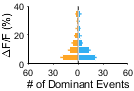

    set(0,'CurrentFigure', figh);
    figQuality(figh,gca,[1.4 .95]);
    set(gca,'LooseInset',get(gca,'TightInset')) ;
    export_fig(['.\EPS Panels\WTGroupHisto.eps'], '-eps', '-nocrop');


%bilateral ablation
    billablFiles = loadFileList('.\Data\*\*ICinfo16_dFoF.mat');
    [bilabl_stats, figh, counts] = groupData_histograms(billablFiles);

M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-582\ICinfo16_dFoF.mat
LIC: 0 peaks total, 0 corresponding RIC peaks.
RIC: 0 peaks total, 0 corresponding LIC peaks.
Mean RIC amplitude: NaN
Mean LIC amplitude: NaN
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-582\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-662\ICinfo16_dFoF.mat


Rdom = 16

tempPkData = 	1.0e+03 *

    0.5940    0.0000    0.5950    0.0000    0.0000    0.0010    0.0010
    0.8790    0.0001    0.8790    0.0001    0.0000    0.0020    0.0010
    1.7710    0.0001    1.7710    0.0001    0.0000    0.0010    0.0010
    1.9160    0.0001    1.9170    0.0001    0.0000    0.0010    0.0010
    2.0930    0.0000    2.0940    0.0000    0.0000    0.0010    0.0010
    2.7380    0.0001    2.7380    0.0000    0.0000    0.0020    0.0010
    5.1650    0.0001    5.1650    0.0001    0.0000    0.0020    0.0010
    5.2120    0.0001    5.2130    0.0001    0.0000    0.0010    0.0010
    5.4190    0.0000    5.4190    0.0000    0.0000    0.0020    0.0010


LIC: 14 peaks total, 10 corresponding RIC peaks.
RIC: 21 peaks total, 10 corresponding LIC peaks.
Mean RIC amplitude: 0.054891
Mean LIC amplitude: 0.050422
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-662\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-677\ICinfo16_dFoF.mat


Rdom = 7


tempPkData =

  0×7 empty double matrix

LIC: 1 peaks total, 1 corresponding RIC peaks.
RIC: 7 peaks total, 1 corresponding LIC peaks.
Mean RIC amplitude: 0.038494
Mean LIC amplitude: 0.027304
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-677\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-678\ICinfo16_dFoF.mat


Rdom = 0

tempPkData = 	1.0e+03 *

    0.1110    0.0000         0         0    0.0000    0.0010    0.0010
    0.2800    0.0000         0         0    0.0000    0.0010    0.0010
    0.5360    0.0000         0         0    0.0000    0.0010    0.0010
    0.9800    0.0000         0         0    0.0000    0.0010    0.0010
    1.4640    0.0000         0         0    0.0000    0.0010    0.0010
    2.4780    0.0001         0         0    0.0001    0.0010    0.0010
    2.8480    0.0000         0         0    0.0000    0.0010    0.0010
    3.9770    0.0001         0         0    0.0001    0.0010    0.0010
    4.1590    0.0001         0         0    0.0001    0.0010    0.0010


LIC: 9 peaks total, 9 corresponding RIC peaks.
RIC: 9 peaks total, 9 corresponding LIC peaks.
Mean RIC amplitude: 0
Mean LIC amplitude: 0.047995
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-678\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-783\ICinfo16_dFoF.mat


Rdom = 1

tempPkData = 	1.0e+03 *

    1.2560    0.0001    1.2560    0.0000    0.0000    0.0020    0.0010
    2.8240    0.0001    2.8240    0.0001    0.0000    0.0010    0.0010


LIC: 3 peaks total, 2 corresponding RIC peaks.
RIC: 2 peaks total, 2 corresponding LIC peaks.
Mean RIC amplitude: 0.054076
Mean LIC amplitude: 0.064698
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-783\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-787\ICinfo16_dFoF.mat


Rdom = 3

tempPkData = 	1.0e+03 *

    0.2150    0.0001    0.2150    0.0001    0.0000    0.0020    0.0010
    2.7610    0.0001    2.7610    0.0000    0.0000    0.0020    0.0010
    3.3710    0.0001    3.3720    0.0001    0.0000    0.0010    0.0010
    4.5540    0.0000    4.5550    0.0000    0.0000    0.0010    0.0010
    4.6650    0.0000    4.6650    0.0000    0.0000    0.0010    0.0010
    5.7040    0.0001    5.7040    0.0001    0.0000    0.0010    0.0010


LIC: 9 peaks total, 7 corresponding RIC peaks.
RIC: 7 peaks total, 7 corresponding LIC peaks.
Mean RIC amplitude: 0.053652
Mean LIC amplitude: 0.052932
M:\Projects and Analysis\Papers\P2ry1\Supp Figure 7p1 - In vivo bilateral ablations\Data\Experiment-787\ICinfo16_dFoF


counts =      0     3     5     1     0     0     0     0     0    12     4     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     7     0     0     0     0     0     0
     0     7     2     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     1     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     6     0     0     0     0     0     0     0     1     2     0     0     0     0     0


Lcounts =     3.4000    1.6000    0.2000         0         0         0         0


Rcounts =     4.2000    1.2000         0         0         0         0         0


    set(0,'CurrentFigure', figh);
    figQuality(figh,gca,[1.4 .95]);
    set(gca,'LooseInset',get(gca,'TightInset')) ;
    export_fig(['.\EPS Panels\bilateralabl_GroupHisto.eps'], '-eps', '-nocrop');

## Compare ko normal and bilateral ablation

%pull leftdom and rightdom total events (not dominant
WT_dom = WT_stats{:,1:2}';
WT_n = size(WT_dom,2);
WT_avg_freq_ind = mean(WT_stats{:,1:2},2)/10;
WT_std = sterr(WT_avg_freq_ind,1)/10;
bilabl_dom = bilabl_stats{:,1:2}';
b_n = size(bilabl_dom,2);
bilabl_avg_freq_ind = mean(bilabl_stats{:,1:2},2)/10;
bilabl_std = sterr(bilabl_avg_freq_ind,1)/10;
% NBQX_dom = NBQX_stats{:,1:2}';
% NBQX_n = size(NBQX_dom,2);

mk_size = 10;
gray = [0.7 0.7 0.7]

gray =     0.7000    0.7000    0.7000


compare2(WT_avg_freq_ind,bilabl_avg_freq_ind,{'P2ry1 KO', 'P2ry1 KO bilateral ablation'}, 'Events per minute',[3 2],[5 12],[0 0 0],[0 0 0])

   9.0419e-07



ans =   Figure (65) with properties:

      Number: 65
        Name: ''
       Color: [1 1 1]
    Position: [0 0 3 2]
       Units: 'inches'

  Show all properties


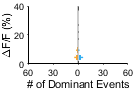

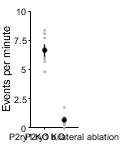

ylim([0 10]);
yticks([0:2.5:10])
figQuality(gcf, gca, [1 1.5]);
export_fig(['.\EPS Panels\group_TotEvents.eps'], '-eps', '-nocrop')


[h,p] = ttest2(WT_avg_freq_ind,bilabl_avg_freq_ind)

h = 1

p = 9.0419e-07

% WT_dom = WT_stats{:,1:2}';
% WT_n = size(WT_dom,2);
% WT_avg_freq_ind = mean(WT_stats{:,4:5},2);
% WT_std = sterr(WT_avg_freq_ind,1);
% bilabl_dom = bilabl_stats{:,1:2}';
% b_n = size(bilabl_dom,2);
% bilabl_avg_freq_ind = mean(bilabl_stats{:,4:5},2);
% bilabl_std = sterr(bilabl_avg_freq_ind,1);
% % NBQX_dom = NBQX_stats{:,1:2}';
% % NBQX_n = size(NBQX_dom,2);
% 
% mk_size = 10;
% gray = [0.7 0.7 0.7]
% compare2(WT_avg_freq_ind,bilabl_avg_freq_ind,{'P2ry1 KO', 'P2ry1 KO bilateral ablation'}, 'Events per minute',[3 2],[5 12],[0 0 0],[0 0 0])
% figQuality(gcf, axh, [1 1.5]);
% export_fig(['.\EPS Panels\group_TotEvents_ampli.eps'], '-eps', '-nocrop')

